# 2017b CCS gyak4. Subspaces. Geometrical meaning.

Author: Peter Polcz <ppolcz@gmail.com> 

Created on 2017.03.09. Thursday, 22:41:56

Reviewed on 2017. October 04.

## Unobservable subspace - seminary example

Starting the system from any initial condition within the unobservability subspace, the output will be the same.

A = [ 1 2 ; -2 -3 ]

A =      1     2
    -2    -3

C = [ 1 1 ]

C =      1     1

O2 = obsv(A,C)

O2 =      1     1
    -1    -1

X_o = null(O2)

X_o =    -0.7071
    0.7071

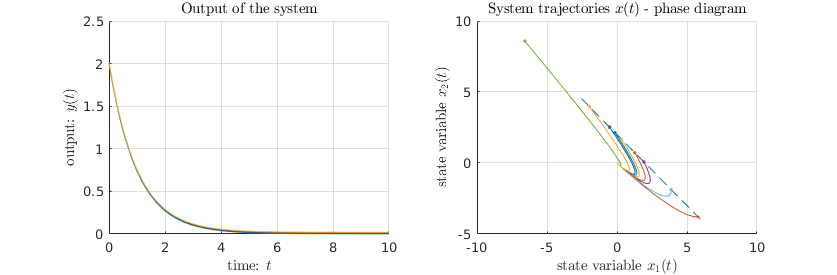

x0 = [ 1 ; 1 ];

figure('Position', [ 668 698 837 275 ], 'Color', [1 1 1]), 
subplot(121), hold on, grid on, ptitle 'Output of the system'
plabel x 'time: $t$'
plabel y 'output: $y(t)$'
subplot(122), hold on, grid on, ptitle 'System trajectories $x(t)$ - phase diagram'
plabel x 'state variable $x_1(t)$'
plabel y 'state variable $x_2(t)$'

x_from = x0 + X_o*(-7);
x_to = x0 + X_o*5;
plot([x_from(1) x_to(1)], [x_from(2) x_to(2)], '--')

for i = 1:10
    x_init = x0 + X_o*randn(size(X_o,2)) * 3;
    [t,x] = ode45(@(t,x) A*x, [0, 10], x_init);
    
    subplot(121)
    Pl = plot(t,rand*0.02 +(C*x')');

    subplot(122)
    plot(x(:,1),x(:,2), 'Color', Pl.Color);
    plot(x(1,1),x(1,2),'.', 'Color', Pl.Color);
end

## Observability staircase form

S = [orth(O2') null(O2)]

S =    -0.7071   -0.7071
   -0.7071    0.7071

A_ = S'*A*S

A_ =    -1.0000    0.0000
    4.0000   -1.0000

C_ = C*S

C_ =    -1.4142    0.0000

## Observability staircase form using SVD

[~,~,S] = svd(O2)

S =    -0.7071   -0.7071
   -0.7071    0.7071

A_ = S'*A*S

A_ =    -1.0000         0
    4.0000   -1.0000

C_ = C*S

C_ =    -1.4142    0.0000

## Controllable subspace - seminary example

Starting the system from any initial condition within the unobservability subspace, the output will be the same.

T = [ -0 , 2 , 2 ; 2 , 0 , 2 ; 0 , -1 , 2 ];
A = [-6 -4 2 ; 2 0 1 ; 0 0 -2];
B = [4 ; 0 ; 0];

Generate a non-trivial jointly not controllable and observable LTI system model.

A = T*A/T; sym(A)

$$ans = \left(\begin{array}{ccc} -1 & 2 & -2\\ -\frac{2}{3} & -6 & \frac{20}{3}\\ -\frac{1}{2} & -1 & -1 \end{array}\right)$$

B = T*B; sym(B)

$$ans = \left(\begin{array}{c} 0\\ 8\\ 0 \end{array}\right)$$

C3 = ctrb(A,B); sym(C3)

$$ans = \left(\begin{array}{ccc} 0 & 16 & -96\\ 8 & -48 & 224\\ 0 & -8 & 48 \end{array}\right)$$

X_C = orth(C3) 

X_C =     0.3832    0.8082
   -0.9036    0.4285
   -0.1916   -0.4041

Simulate the system with a noisy sinusoid input signal.

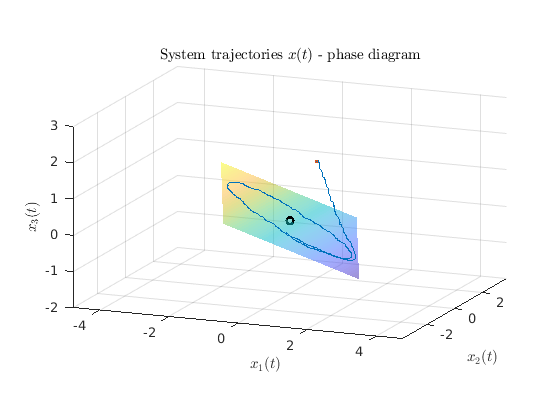

u = @(t) randn + sin(t);
[tt,xx] = ode45(@(t,x) A*x + B*u(t), [0,10], 2*null(X_C') + X_C * randn(size(X_C,2),1));

% Plot trajectory and the initial state
figure, hold on
plot3(xx(:,1),xx(:,2),xx(:,3));
plot3(xx(1,1),xx(1,2),xx(1,3),'.');

% Plot the plane corresponding to the controllable subspace
syms u v real
vekanal_plot_sym_surface(X_C * [u;v], ...
    u,v,[-2 2], [-2 2], 'resolution', 2, 'args', ...
    {'facealpha', 0.5, 'FaceColor',[1 0 0]}),
shading interp, grid on
plot3(0,0,0, 'ok', 'Markersize', 5, 'LineWidth', 2)

% Just to be fancy...
axis equal
ptitle 'System trajectories $x(t)$ - phase diagram'
plabel x '$x_1(t)$'
plabel y '$x_2(t)$'
plabel z '$x_3(t)$'
zlim([-2 3])
view([22.03 13.39]), snapnow

## Controllability staircase form

S = [orth(C3) null(C3')]

S =     0.3832    0.8082   -0.4472
   -0.9036    0.4285   -0.0000
   -0.1916   -0.4041   -0.8944

A_ = S'*A*S

A_ =    -4.3791    5.6543    5.7611
   -0.1595   -1.6209   -1.0718
    0.0000    0.0000   -2.0000

B_ = S'*B

B_ =    -7.2285
    3.4277
   -0.0000

## Controllability staircase form using SVD

[S,~,~] = svd(C3)

S =     0.3832    0.8082    0.4472
   -0.9036    0.4285         0
   -0.1916   -0.4041    0.8944

A_ = S'*A*S

A_ =    -4.3791    5.6543   -5.7611
   -0.1595   -1.6209    1.0718
    0.0000   -0.0000   -2.0000

B_ = S'*B

B_ =    -7.2285
    3.4277
         0